# Tarjeta de audio

## Escanear dispositivos de audio

audioInfo=audiodevinfo

audioInfo = struct with fields:
     input: [1×8 struct]
    output: [1×8 struct]


## Crear objeto de audio

Id=-1;
fs=8000; %Frecuencia de muestreo [Hz]
CH_No=1; %No. de canales de entrada (Stereo [2] o mono [1]
BitDepth=8; %Profundidad de Bits por muestra

%Default: fs=8kHz, BitDepth=8 bit, 1CH
recordObject=audiorecorder(fs,BitDepth,CH_No,Id) %Objeto de grabación

recordObject =   audiorecorder with properties:

       SampleRate: 8000
    BitsPerSample: 8
      NumChannels: 1
         DeviceID: -1
    CurrentSample: 1
     TotalSamples: 0
          Running: 'off'
         StartFcn: []
          StopFcn: []
         TimerFcn: []
      TimerPeriod: 0.0500
              Tag: ''
         UserData: []
             Type: 'audiorecorder'


%recordObject=audiorecorder Objeto de grabación default



## GRabación

T=3; %Tiempo de grabación [s]
recordblocking(recordObject,T); %Comienza a grabar y remplaza las siguientes dos


## Ploteo

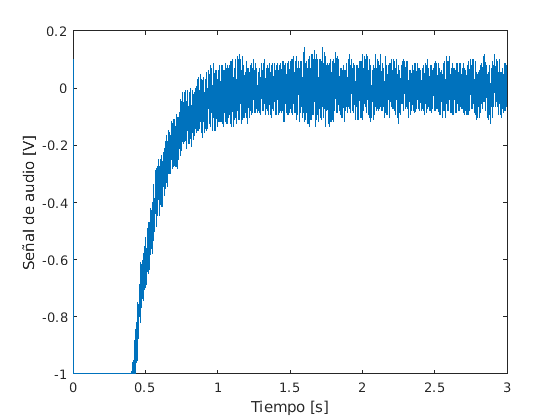

data_grabacion=getaudiodata(recordObject); %Guarda el audio como un arreglo 

%Vector de tiempo
%Ts=1/fs
t=1/fs:1/fs:T;
plot(t,data_grabacion)
xlabel("Tiempo [s]")
ylabel("Señal de audio [V]")

## Reproducción

%play(recordObject); Reproduce la grabación
sound(data_grabacion,fs);
%sound(data_grabacion,fs*2);


## Espectro

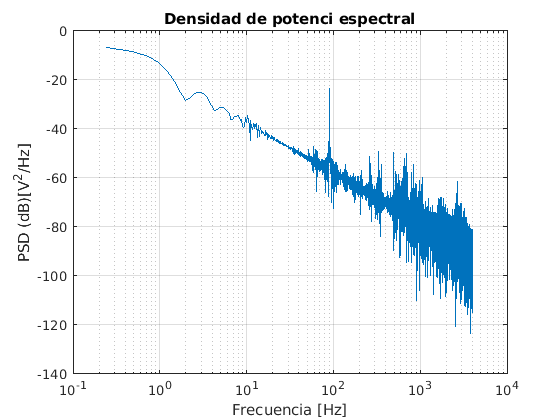

%Parámetros importantes
N=numel(data_grabacion); %Número de muestras
N_spect=N/50; %Número de muestras del espectrograma

%Funciones de descomposición espectral
[Pxx_Per,F_Pxx]=periodogram(data_grabacion,rectwin(N),[],fs);
[~,F_Spec,T_Spec,Pxx_Spec]=spectrogram(data_grabacion,rectwin(N_spect),[],[],fs);
%Time-Frequency ridge: Busca la oscilación más fuerte en un espectrograma
%fr=tfridge(Pxx_Spec,F_Spec);

%Periodograma
figure
semilogx(F_Pxx,10*log10(Pxx_Per))
title("Densidad de potenci espectral")
xlabel("Frecuencia [Hz]")
ylabel("PSD (dB)[V^2/Hz]")
grid on

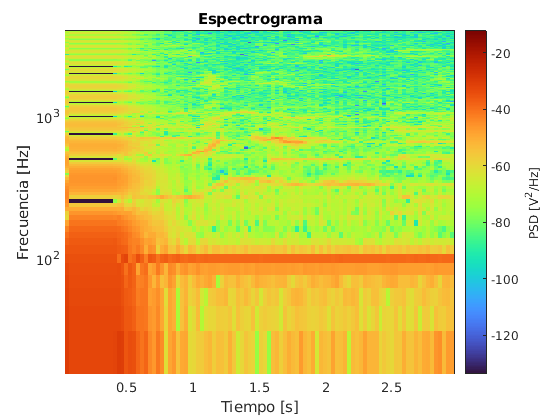


%Espectrograma
figure
p=pcolor(T_Spec,F_Spec,10*log10(Pxx_Spec));
set(p,'EdgeColor','none')
xlabel("Tiempo [s]")
ylabel("Frecuencia [Hz]")
title("Espectrograma")
c=colorbar;
c.Label.String="PSD [V^2/Hz]";
colormap('turbo')

set(gca,'Yscale','log')

## Sin argumentos de salida

Periodograma y espectrograma defaul

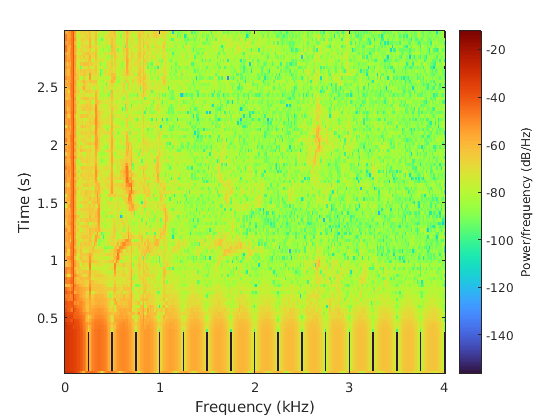

spectrogram(data_grabacion,rectwin(N_spect),[],[],fs);

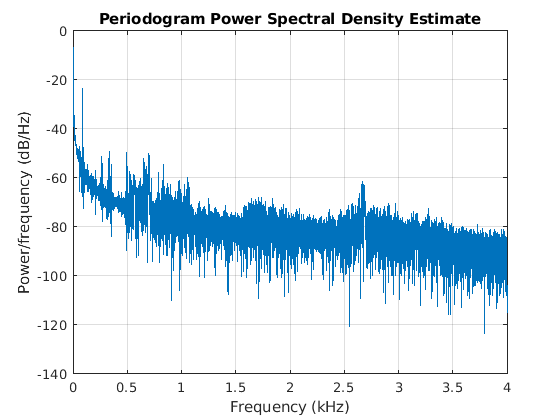

periodogram(data_grabacion,rectwin(N),[],fs);

## Guardar audio

%Guardar audio
audiowrite("Output/voz.wav",data_grabacion,fs)
%Guardar matrices
%writematrix
%Guardar tablas
%writetable